## Tópicos especiais em Estatística Aplicada - 2023/2

## EPC4

## Aluno: João Gabriel Santos Custodio

clc; clear variables

Seja a variável aleatória X com distribuição uniforme com 1000 amostras e intervalo [a,b] utilizada no EPC3. Foram utilizadas N=20 amostras de X para calcular 50 valores de média $\bar{x}$.

X = 50.*rand(1,1000);

1. Plote o gráfico da pdf de X, escolha um nível de confiança 1 − α e delimite as regiões de aceitação e regiões críticas, mostrando-as no gráfico da pdf de X̅

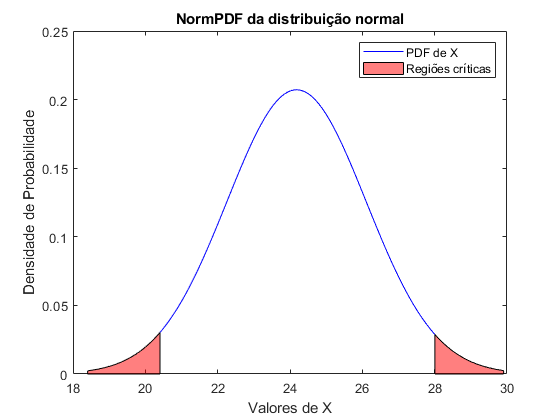

alpha = 0.05;
% Defina o número de amostras para a média amostral X̅, N
num_samples = 50;
% Inicialize um vetor para armazenar as médias amostrais
means_Xbar = zeros(1, num_samples);
for i = 1:num_samples
    sample = randsample(X, num_samples, true);
    means_Xbar(i) = mean(sample);
end

mu = mean(means_Xbar);
sigma = std(means_Xbar);
x_axis = mu - 3 * sigma:0.1:mu + 3 * sigma;
pdf = normpdf(x_axis, mu, sigma);

% Calcule os valores de zalpha e z1alpha
zalpha = norminv(alpha / 2, mu, sigma);
z1alpha = norminv(1 - alpha / 2, mu, sigma);

% Crie os vetores x_area e y_area para a área a ser preenchida para os
% valores do intervalo de confiança inferior
x_area = x_axis(x_axis <= zalpha);
y_area = pdf(x_axis <= zalpha);

% Plote o gráfico da PDF
figure();
plot(x_axis, pdf, 'b');
hold on;

% Pinte a área sob o gráfico da PDF para valores menores que zalpha e maiores que z1alpha
fill([x_area, fliplr(x_area)], [y_area, zeros(size(y_area))], 'r', 'FaceAlpha', 0.5);

% Crie os vetores x_area e y_area para a área a ser preenchida para valores
% do intervalo de confiança superior
x_area = x_axis(x_axis >= z1alpha );
y_area = pdf(x_axis >= z1alpha);
hold on
% Plote o gráfico da PDF

% Pinte a área sob o gráfico da PDF entre zalpha e z1alpha
fill([x_area, fliplr(x_area)], [y_area, zeros(size(y_area))], 'r', 'FaceAlpha', 0.5);


title("NormPDF da distribuição normal");
xlabel('Valores de X');
xlim = [21;30.3];
ylim = [0;0.2];
ylabel('Densidade de Probabilidade');
legend('PDF de X', 'Regiões críticas', 'Location', 'northeast');
hold off

2. Para que valor da estatística de teste $\bar{X}$ tem-se p − valor ≤ α/10 ?

Como foi definido α = 0.05 na questão anterior, temos:


$$\begin{array}{l}
p-\textrm{valor}\le \frac{0\ldotp 05}{10}\\
p-\textrm{valor}\le 0\ldotp 005
\end{array}$$


Dessa forma, devemos encontrar os dois valores que dividem o p-valor em duas áreas que equivalem a 0.005/2, ou seja, 0,25% para cada área.

x_barra_inf = norminv(0.5*(alpha/10),mu,sigma)

x_barra_inf = 18.7765

x_barra_sup = norminv(1-0.5*(alpha/10),mu,sigma)

x_barra_sup = 29.5856

Portanto, os valores de estatística de teste $\bar{X}$ que satisfazem  p − valor ≤ α/10 são:

$\bar{X} \le 18\ldotp 7765$ ou $\bar{X} \ge 29\ldotp 5856$

3. Sugira um teste de hipótese para a média de modo que se tenha probabilidade de erro tipo I igual a α e probabilidade de erro tipo II β = 0.2. Repita para β = 0.5.

Assumindo que o teste de hipótese seja do tipo bilateral, o erro do tipo 1 (α) correponde à região semelhantes à ilustrada no gráfico da questão 1, e o erro do tipo 2 (β) corresponde à região entre as regiões críticas do erro tipo 1.

Dessa forma, podemos afirmar que β+α = 1.

Sendo assim, pode-se utilizar a função norminv e encontrar os limites da região de β

b = 0.2;
a = 1-b;
teste_q3_1 = norminv(a/2, mu, sigma)

teste_q3_1 = 23.5572

teste_q3_2= norminv(1-(a/2), mu, sigma)

teste_q3_2 = 24.5693

 Concluí-se, portanto, que para β=0.2 região de aceitação fica entre $\bar{X} \ge 25\ldotp 5572$ e   $\bar{X} \le 24\ldotp 5693$ e um possível teste de hipótese seria $H_0 =23\ldotp 5572$ e $H_{1\;} =24\ldotp 5693$.

Se mudarmos o valor de beta para β=0.5, é de imediato que α=0.5, logo podemos calcular da mesma forma que anteriormente os limites da região de interesse do erro tipo 2.

b = 0.5;
a = b;
teste_q4_3= norminv(a/2, mu, sigma)

teste_q4_3 = 22.7159

teste_q4_4 = norminv(1-(a/2), mu, sigma)

teste_q4_4 = 25.4106

Logo, definindo β=0.5, a região de aceitação fica entre $\bar{X} \ge 22\ldotp 7159$ e $\bar{X} \le 25\ldotp 4106$ e um possível teste de hipótese seria $H_0 =22\ldotp 7159$ e $H_{1\;} =25\ldotp 4106$

4. Altere N para aumentar o poder de teste de 50% para 75% (β = 0.5 para β = 0.25). Ilustre a solução graficamente na pdf.

beta = 0.25;
z1 = norminv(beta/2)

z1 = -1.1503

z2 = norminv(1-beta/2)

z2 = 1.1503

beta = 0.5;
beta1 = norminv((beta/2), mu, sigma);
beta2 = norminv(1-((beta/2)), mu, sigma);
N1 = round((z1^2*sigma^2)/(beta1-mu)^2)

N1 = 3

N2 = round((z2^2*sigma^2)/(beta2-mu)^2)

N2 = 3

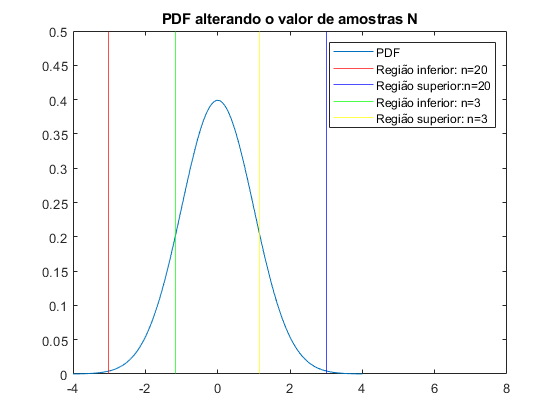

mu_padrao = 0;
std_padrao = 1;
x_padrao = mu_padrao-4*std_padrao:0.01:mu_padrao+4*std_padrao;
y_padrao = normpdf(x_padrao, mu_padrao, std_padrao);

figure
plot(x_padrao, y_padrao);
eixo_atual = gca;
% Ajuste os limites do eixo x
eixo_atual.XLim = [-4, 8];
eixo_atual.YLim = [0, 0.5];

z1 = (beta1 - mu) / (sigma / sqrt(20));
z2 = (beta2 - mu) / (sigma / sqrt(20));
z3 = (beta1 - mu) / (sigma / sqrt(N1));
z4 = (beta2 - mu) / (sigma / sqrt(N2));
xline(z1, 'r')
xline(z2, 'b')
xline(z3, 'g')
xline(z4, 'y')
title('PDF alterando o valor de amostras N')
legend('PDF','Região inferior: n=20','Região superior:n=20', ...
    'Região inferior: n=3', 'Região superior: n=3' )


$$z_x =\frac{\beta -\mu }{\frac{\sigma }{\sqrt{n}}}$$


A partir da fórmula acima do teste estatístico é possível isolar o "n" da equação e encontrar quanto que vale z para um determinado número de amostras. Como é de interesse encontrar para $\beta$ = 0.25 e n=20 encontra-se que z_1,2 = [-1.1503 1.1503]. Como devemos alterar N para que β seja -0.25, basta utilizar os valores de z_1 e z_2 para encontrar o valor de "n" com a equação acima. Fazendo esses cálculos, foi encontrado que para ambos os casos n = 2,9088 e como "n" tem que ser um valor natural, por isso foi utilizado a função round no cálculo dos Ns para truncar o resultado para 3.

Dessa forma, o poder de teste é aumentado para 75% como foi solicitado.

5. Use o teste estatístico z (ztest) para verificar se a variável aleatória X̅ do item 1 tem distribuição normal com a média e desvio padrão conhecidos da população X. Interprete as saídas do teste: h (0 ou 1), valor-p, CI, zval (estatística de teste), e mostre graficamente estas informações na pdf. Complemente a análise usando um gráfico normal probability plot ( função normplot no Matlab).

mu_ztest = mean(X);
sigma_ztest = std(X);
[h,p,ci,zval] = ztest(means_Xbar, mu_ztest, sigma_ztest)

h = 0

p = 0.9069

ci =    20.2610   28.1012


zval = -0.1169

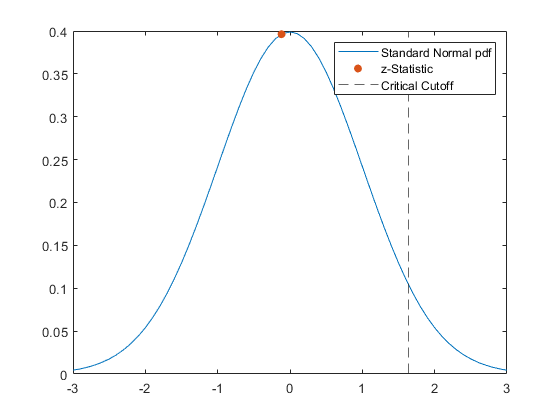

mu_q5 = 0;
sigma_q5 = 1;
x_axis_q5 = mu_q5 - 3 * sigma_q5:0.1:mu_q5+ 3 * sigma_q5;
y = normpdf(x_axis_q5, mu_q5, sigma_q5);
zvalpdf = normpdf(zval);
zcrit = norminv(0.95);
figure
plot(x_axis_q5,y);
hold on
scatter(zval,zvalpdf,"filled")
xline(zcrit,"--")
legend(["Standard Normal pdf","z-Statistic", "Critical Cutoff"])

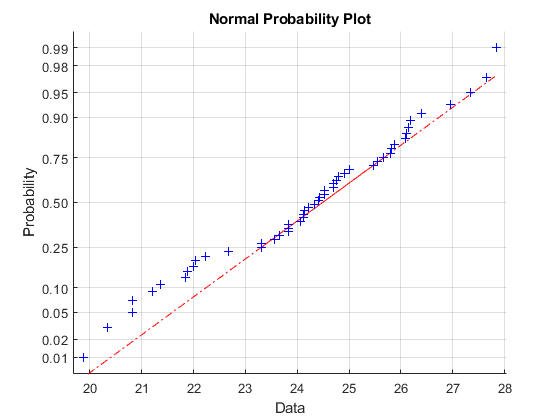

figure
normplot(means_Xbar)

Interpretando os resultados do ztest:

- h = 0  nos indica que a hipótese nula não pode ser rejeitada.

- valor-p = 0.9069 nos mostra que temos poucas evidências para rejeitar a hipótese nula.

- ci = [20.2610 , 28,1012] é a região de confiabilidade onde a média populacional verdadeira tem 100 × (1 – [`Alpha`](https://www.mathworks.com/help/stats/ztest.html#btqjrtc_sep_shared-Alpha))% de confiança

- zval = -0.1169 indica o quanto média da amostra desvia da média populacional em termos de desvios padrão. Neste caso, um valor-Z negativo indica que a média da amostra está ligeiramente abaixo da média populacional.